syms x;

y = 10^(-x / 10)

$$y = \frac{1}{10^{x/10}}$$


factorial(3)

ans = 6

4*150

ans = 600

n = 1;
cosn = (-1)^n*factorial(2*n)/factorial(n)/factorial(2*n-1)

cosn = -2

lo = -2.2*log10(cosn)

lo = -0.6623 - 3.0016i

10^lo

ans = 0.1761 - 0.1279i

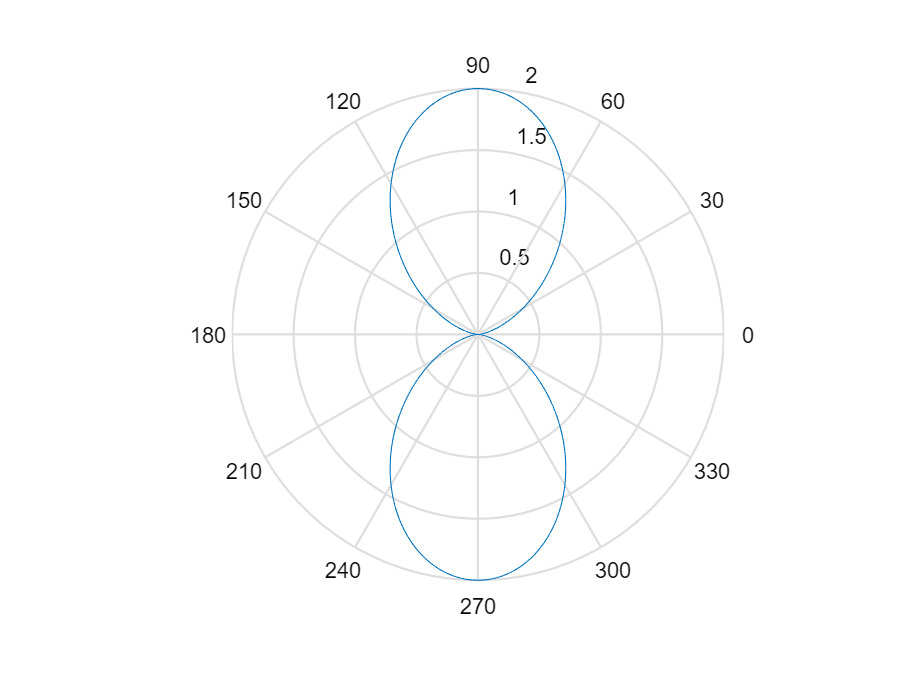

 f=3e10;
 lamda=(3e8)/f;
 beta=2.*pi/lamda; 
 t=0:0.01:2*pi;
 d=lamda/2; 
 alpha = 0;

 W=0.5*beta.*d.*cos(t)-alpha./2;
%  F1=sin(z1)./(n.*sin(z2));
 F1=2*cos(W);
 K1=abs(F1);
 polar(t,K1);

验证cos(nx)与cosx之间关系是否相等

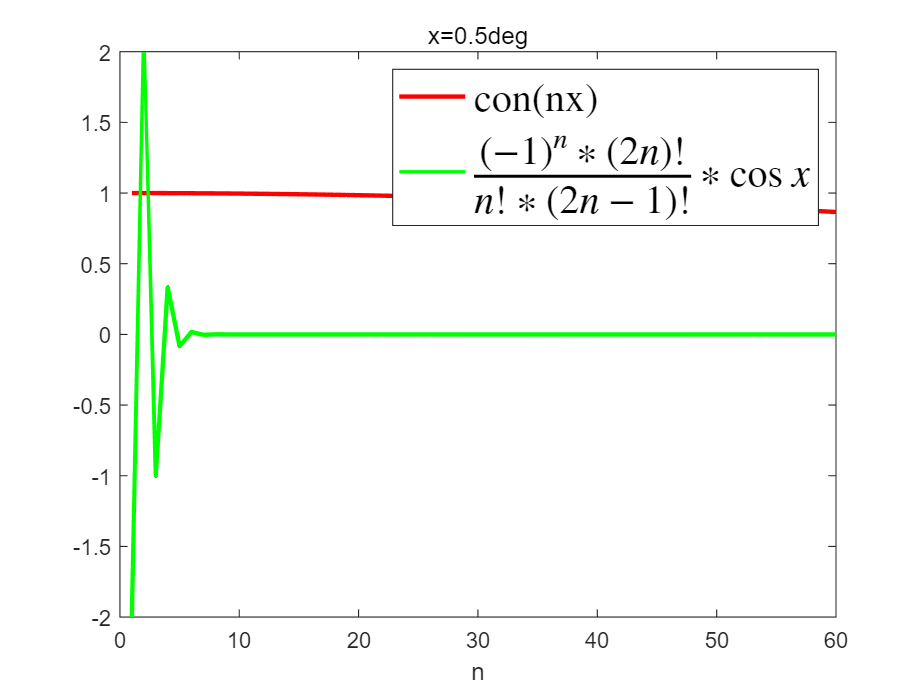

% clear all;
% close all;
x = 0.5;
n = 1:60;
y1 = cosd(n*x);
y2 = (-1).^n.*factorial(2*n)./factorial(n)./factorial(2*n-1)*cosd(x);
plot(n,y1,'r',LineWidth=2);
hold on;
plot(n,y2,'g',LineWidth=2);
xlabel('n')
title('x=0.5deg')
legend('con(nx)', '$\frac{(-1)^{n} *(2 n)!}{n!*(2 n-1)!} * \cos x$','Interpreter', 'latex','Fontsize',18)

验证加绝对值前后的指数是否相等

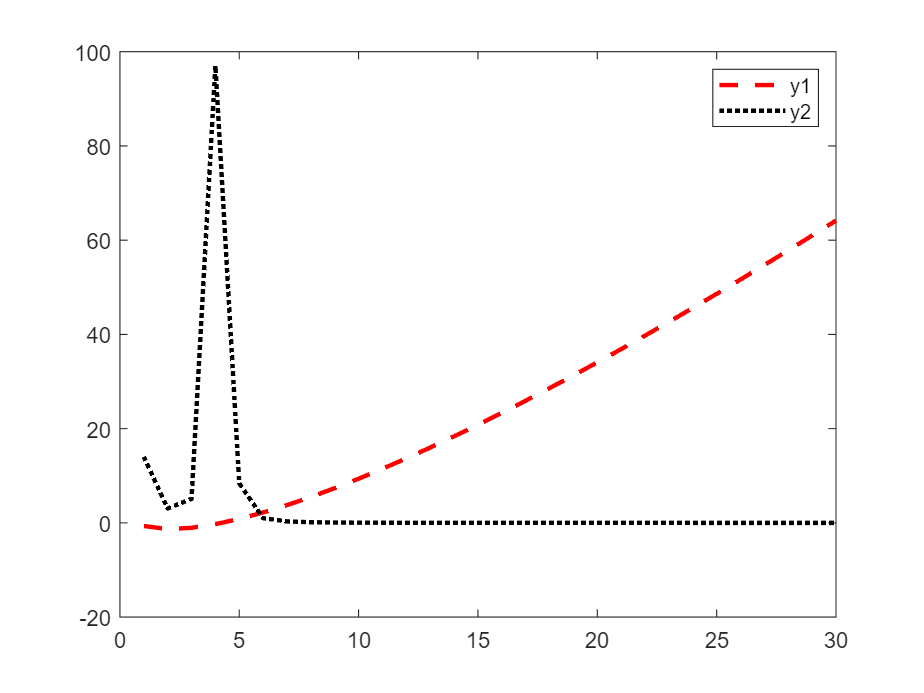

close;
clear all;
n = 1:30;
y1 = log10((2*n./factorial(n-1)).^(-2.2));
y2 = abs(log10((2*n./factorial(n-1)))).^(-2.2);
figure(1)
plot(n, y1, 'r', LineStyle='--', LineWidth=2);
hold on;
plot(n, y2, 'k', LineStyle=':', LineWidth=2);
legend('y1', 'y2')

R = 6371e3;
pi*R/180

ans = 1.1119e+05

pi/6

ans = 0.5236

275*22

ans = 6050

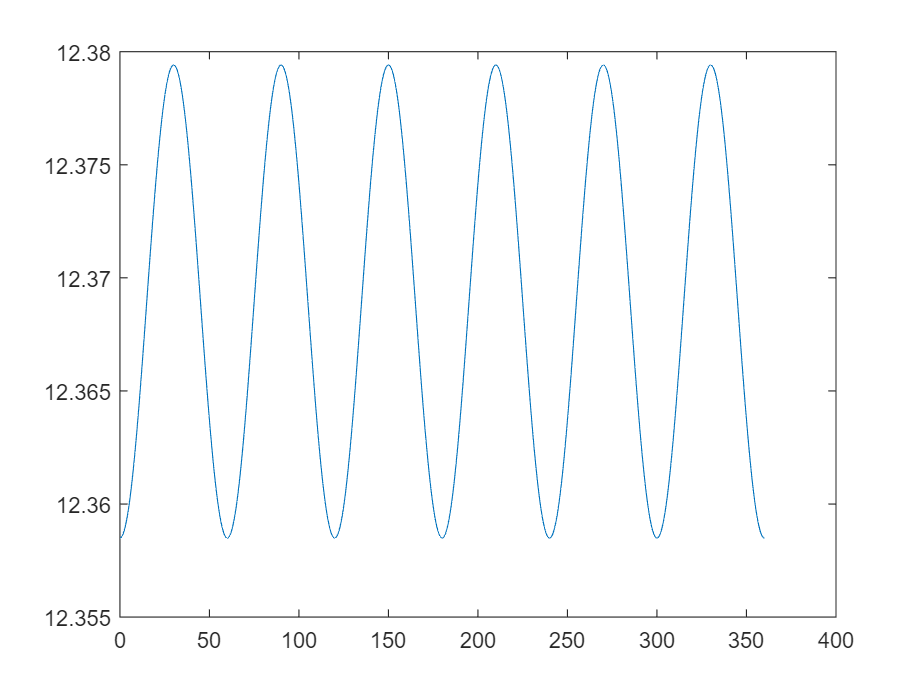

close
clear all;
d = 200;
h = 50;
d_uav = 50;
pos = zeros(7,2);
for i = 2:7
    pos(i, :) = [d*cosd(60*(i-2)), d*sind(60*(i-2))];
end
theta = 0:0.3:360;
pos_uav = [d_uav*cosd(theta); d_uav*sind(theta)];
alpha1 = atand(h/d_uav);
interfere = zeros(6,length(theta));
for i = 2:7
    distance1 = sqrt((pos(i,1)-pos_uav(1,:)).^2 + (pos(i,2)-pos_uav(2,:)).^2);
    alpha2 = atand(h./distance1);
    distance2 = sqrt(pos_uav(1,:).^2 + pos_uav(2,:).^2);
    n = distance1./distance2;
    interfere(i-1, :) = 10.^((-2.2)*log10(cosd(alpha2)/cos(alpha1).*n));
end
sinr = 1./sum(interfere,1);
plot(theta, sinr);